# Generate

s = daq.createSession('ni');
dev = daq.getDevices().ID;
addAnalogOutputChannel(s, dev, 'ao0','voltage'); 
addAnalogInputChannel(s, dev, 'ai1', 'voltage');
s.Rate = 1000000;

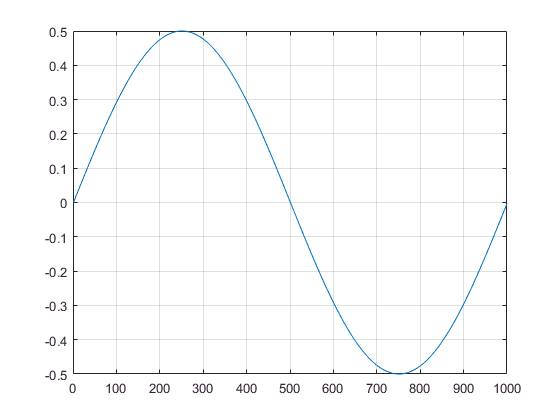


data = 0.5*sin(linspace(0, 2*pi, 1001))';

% removing the last point
% linspace always include the last digit
% but we want it just before 2*pi
data(end) = [];
plot(data)
grid on;

## queue the output data and start Background gen

%queueOutputData(s, repmat(data, 5,1));
%s.startBackground();

% handler
lh1 = addlistener(s, 'DataRequired', @genData);
lh = addlistener(s, 'DataAvailable', @plotData);


s.IsContinuous = true;
queueOutputData(s, repmat(data, 500, 1))

s.startBackground();

s.stop()
delete([lh, lh1])

function plotData(src, event)
    plot(event.TimeStamps, event.Data)
end

function genData(src, event)
    data = 0.5*sin(linspace(0, 2*pi, 1001))';
    data(end) = [];
    queueOutputData(src, repmat(data, 50, 1))
end